clear;
clc;
run = load("20SStableRunBaleka.mat");

dy = timeseries2timetable(run.data{2}.Values.dy);
y = timeseries2timetable(run.data{2}.Values.y);

dx = timeseries2timetable(run.data{2}.Values.dx);

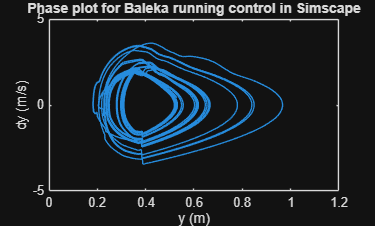

% Final plots
plot(y.y,dy.dy);
hold on
xlabel("y (m)")
ylabel("dy (m/s)")
title("Phase plot for Baleka running control in Simscape")
axis([0 1.2 -5 5])
hold off

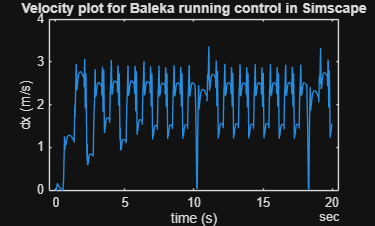


plot(dx.Time, dx.dx)
hold on
xlabel("time (s)")
ylabel("dx (m/s)")
title("Velocity plot for Baleka running control in Simscape")
hold off